# **Κεφάλαιο 2: Ταξινομητές που βασίζονται στη βελτιστοποίηση συνάρτησης κόστους - Ο αλγόριθμος Perceptron**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## Ο αλγόριθμος  perceptron

### Παράδειγμα 1

Δημιουργήσετε 4 διδιάστατα σύνολα δεδομένων $X_i,i=1,...,4$ κάθε ένα εκ των οποίων περίεχει διανύσματα δεδομένων δύο κλάσεων. Σε κάθε $X_i$ η πρώτη κλάση (συμβολίζεται με -1) περιέχει $100$ διανύσματα που είναι ομοιόμορφα κατανεμημένα στην περιοχή $[0,2]\times [0,2]$. Η δεύτερη κλάση (συμβολίζεται με +1) περιέχει άλλα 100 διανύσματα που είναι ομοιόμορφα κατανεμημένα στις τετραγωνικές περιοχές $[3,5]\times [3,5], [2,4]\times [2,4], [0,2]\times [2,4]$ και $[1,3]\times [1,3]$ για τα $X_1, X_2, X_3, X_4$ αντιστοίχως. Κάθε διάνυσμα δεδομένων επαυξάνεται με μια τρίτη συντεταγμένη ίση με $1$.

- Δώστε την γραφική παράσταση των τεσσάρων συνόλων δεδομένων και παρατηρήστε  ότι καθώς κινούμαστε από το $X_1
$ στο $X_3$ οι κλάσεις πλησιάζουν η μία την άλλη, αλλά παραμένουν γραμμικώς διαχωρίσιμες. Στο $X_4$ οι κλάσεις επικαλύπτονται.

- Τρέξτε τον αλγόριθμο perceptron για το κάθε σύνολο $X_i$ με ρυθμό μάθησης 0.01 και 0.05 και αρχική εκτίμηση του διανύσματος παραμέτρων την $[1,1,-0.5]^T$

- Τρέξτε τον αλγόριθμο perceptron για το σύνολο $X_3$ με ρυθμό μάθησης 0.05 και αρχική εκτίμηση του διανύσματος παραμέτρων την $[1,1,-0.5]^T$ και $[1,1,0.5]^T$

-  Σχολιάστε τα αποτελέσματα.

close('all');
clear

rand('seed',0);

% Generate the dataset X1 as well as the vector containing the class labels of
% the points in X1 
N=[100 100]; % 100 vectors per class
l=2; % Dimensionality of the input space

%x=[3 3]';
%x=[2 2]'; %for X2
x=[0 2]'; %for X3
%x=[1 1]'; %for X4

X1=[2*rand(l,N(1)) 2*rand(l,N(2))+x*ones(1,N(2))];
X1=[X1; ones(1,sum(N))];
y1=[-ones(1,N(1)) ones(1,N(2))];

% 1. Plot X1, where points of different classes are denoted by different colors,
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'bo',...
X1(1,y1==-1),X1(2,y1==-1),'r.')
figure(1), axis equal
% 2. Run the perceptron algorithm for X1 with learning parameter 0.01
rho=0.01; % Learning rate
w_ini=[1 1 -.5]';
[w,iter,mis_clas]=perce(X1,y1,w_ini,rho)


 First Iteration: # Misclassified points = 95 


w =     0.0050
    0.5019
   -1.0104


iter = 5441

mis_clas = 0

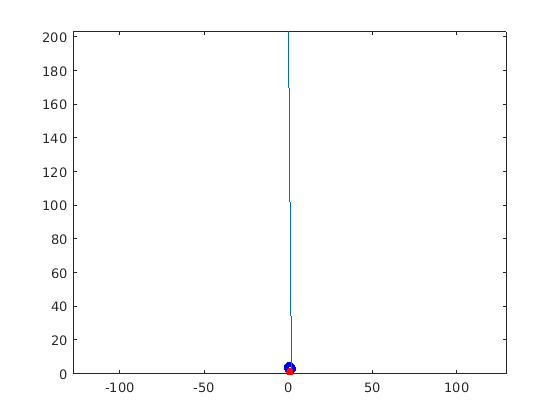

% this is the equation of the line defined by the learnt weights
% the slope of the line is m=w(2)/w(1), the bias a=(-w(3)/w(1))
% y=mx+a that is: y=(w(2)/w(1))*x+(-w(3)/w(1))
%xx = [0 -w(3)/w(2)];
%yy = [-w(3)/w(1) 0];
%line(xx,yy)

## Η online εκδοση του αλγόριθμου Perceptron

### Παράδειγμα 1

Τρέξτε την online έκδοση του αλγόριθμου perceptron για τα σύνολα δεδομένων του προηγούμενου παραδείγματος, χρησιμοποιώντας ρυθμό μάθησης ίσο με 0.01 και 0.05 και αρχική εκτίμηση του διανύσματος παραμέτρων την $[1,1,-0.5]^T$. Σχολιάστε τα αποτελέσματα.

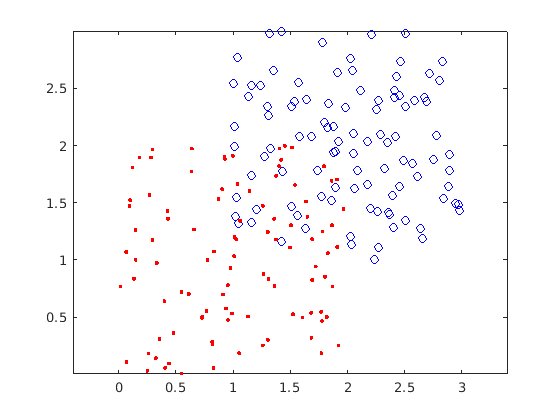

close('all');
clear

rand('seed',0);

% Generate the dataset X1 as well as the vector containing the class labels of
% the points in X1 
N=[100 100]; % 100 vectors per class
l=2; % Dimensionality of the input space

%x=[3 3]';
% x=[2 2]'; for X2
% x=[0 2]'; for X3
 x=[1 1]'; %for X4

X1=[2*rand(l,N(1)) 2*rand(l,N(2))+x*ones(1,N(2))];
X1=[X1; ones(1,sum(N))];
y1=[-ones(1,N(1)) ones(1,N(2))];

% 1. Plot X1, where points of different classes are denoted by different
% colors
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'bo',...
X1(1,y1==-1),X1(2,y1==-1),'r.')
figure(1), axis equal


% 2. Run the perceptron algorithm for X1 with learning parameter 0.01
rho=0.01; % Learning rate
%rho=0.05
w_ini=[1 1 -0.5]';
[w,iter,mis_clas]=perce_online(X1,y1,w_ini,rho)

w =     0.1138
    0.1215
   -0.2600


iter = 10000000

mis_clas = 6

## Ταξινομητής ελάχιστου τετραγωνικού σφάλματος

### Παράδειγμα 1

1. Δημιουργήστε ένα σύνολο $X_1$ που αποτελείται από $N_1=200$ διανύσματα δεδομένων, έτσι ώστε τα πρώτα μισά από αυτά να ανήκουν στην κλάση $\omega_1$ που μοντελοποιείται με Gaussian κατανομή μέσης τιμής $m_1=[0, 0, 0, 0, 0]^T$. Τα υπόλοιπα προέρχονται από την κλάση $\omega_2$, η οποία μοντελοποιείται με Gaussian κατανομή μέσης τιμής $m_2=[1,1,1,1,1]^T$. Το μητρώο συνδιασποράς είναι κοινό και ίσο με:


$$S=\left[ \matrix
{0.9 & 0.3 & 0.2 & 0.05 & 0.02 \cr
 0.3 & 0.8 & 0.1 & 0.2 & 0.05 \cr
0.2 & 0.1 & 0.7 & 0.015 & 0.07 \cr
0.05 & 0.2 & 0.015 & 0.8 & 0.01 \cr
0.02 & 0.05 & 0.07 & 0.01 & 0.75

} \right]$$


Στη συνέχεια δημιουργήστε ένα επιπλέον σύνολο δεδομένων $X_2$ από  διανύσματα δεδομένων, ακολουθώντας την συνταγή για το $X_1$. Εφαρμόστε τον βέλτιστο  Bayesian ταξινομητή στο $X_2$ και υπολογίστε το σφάλμα ταξινόμησης.

2. Επαυξήστε κάθε διάνυσμα χαρακτηριστικών στα $X_1,X_2$ προσθέτοντας μια τελευταία συντεταγμένη ίση με 1. Στη συνέχεια ορίστε τις ετικέτες κλάσεις $-1$ και $+1$  για τις δύο κλάσεις αντίστοιχα. Χρησιμοποιώντας το σύνολο $X_1$ ως σύνολο εκπαίδευσης, εφαρμόστε την συνάρτηση *SSErr* με $C=0$ για να λάβετε την LS εκτίμηση $\hat{w}$. Κατόπιν, χρησιμοποιήστε την εκτίμηση αυτή για να ταξινομήσετε τα διανύσματα του $X_2$ σύμφωνα με την ανισότητα:


$$\hat{w}^Tx>(<)0$$


Υπολογίστε την πιθανότητα σφάλματος. Να συγκριθούν τα αποτελέσματα αυτά με αυτά του βήματος 1.

3. Να επαναληφθούν τα παραπάνω βήματα 2 φορές. Την πρώτη φορά το $X_2$ να αντικατασταθεί με ένα σύνολο $X_3$ που περιέχει $N_3=10000$ διανύσματα δεδομένων και την δεύτερη φορά με ένα σύνολο $X_4$ που περιέχει $N_4=100000$ διανύσματα δεδομένων. Τα $X_3$ και $X_4$ δημιουργούνται με βάση τη συνταγή για το $X_1$. Σχολιάστε τα αποτελέσματα.

close('all');
clear;

% 1.
m(:,1)=[0 0 0 0 0]';
m(:,2)=[1 1 1 1 1]';
S=[.9 .3 .2 .05 .02; 
     .3 .8 .1 .2 .05;
     .2 .1 .7 .015 .07; 
     .05 .2 .015 .8 .01; 
     .02 .05 .07 .01 .75];
P=[1/2 1/2];

% Generate X1 and the required class labels
N1=200;
randn('seed',0)
X1=[mvnrnd(m(:,1),S,fix(N1/2)); mvnrnd(m(:,2),S,N1-fix(N1/2))]';
z1=[ones(1,fix(N1/2)) 2*ones(1,N1-fix(N1/2))];

% Generate X2 and the required class labels
%N2=200;
% N2=10000 % for X3
 N2=100000 % for X4

N2 = 100000

randn('seed',100)
X2=[mvnrnd(m(:,1),S,fix(N2/2)); mvnrnd(m(:,2),S,N2-fix(N2/2))]';
z2=[ones(1,fix(N2/2)) 2*ones(1,N2-fix(N2/2))];

% Compute the Bayesian classification error based on X2
S_true(:,:,1)=S;
S_true(:,:,2)=S;
[z]=bayes_classifier(m,S_true,P,X2);
err_Bayes_true=sum(z~=z2)/sum(N2)

err_Bayes_true = 0.1467

% 2. Augment the data vectors of X1 
X1=[X1; ones(1,sum(N1))];
y1=2*z1-3;

% Augment the data vectors of X2
X2=[X2; ones(1,sum(N2))];
y2=2*z2-3;

% Compute the classification error of the LS classifier based on X2
[w]=SSErr(X1,y1,0);
SSE_out=2*(w'*X2>0)-1; % testing on X2
err_SSE=sum(SSE_out.*y2<0)/sum(N2)

err_SSE = 0.1475

### Παράδειγμα 2

Δημιουργήστε ένα σύνολο από $N_1=1000$ διανύσματα δεδομένων, έτσι ώστε τα πρώτα μισά διανύσματα να προέρχονται από την κλάση $\omega_1$ που μοντελοποιείται με Gaussian κατανομή μέσης τιμής $m_1=[0,0,0,0,0]^T$, ενώ τα υπόλοιπα να ανήκουν στην κλάση $\omega_2$ που μοντελοποιείται με Gaussian κατανομή μέσης τιμής $m_2=[2,2,0,2,2]^T$. Το μητρώο συνδιασποράς είναι κοινό και ίσο με:


$$S=\left[ \matrix
{1 & 0 & 0 & 0 & 0 \cr
 0 & 1 & 0 & 0 & 0 \cr
0 & 0 & 10^{-350} & 0 & 0 \cr
0 & 0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 0 & 1

} \right]$$


Κάθε διάνυσμα δεδομένων επαυξάνεται με μια έκτη συντεταγμένη που ισούται με $1$ για όλα τα διανύσματα. Έστω $X_1$ το $(l+1)XN$ μητρώο με στήλες τα διανύσματα του συνόλου δεδομένων. Επίσης δημιουργήστε ένα σύνολο $X_2$ που περιέχει $10000$ σημεία, ακολουθώντας την συνταγή για το $X_1$.

- Υπολογίστε τον αριθμό συνθήκης (condition number) του μητρώου $X_1X_1^T$ (όσο μεγαλύτερος είναι αυτός ο αριθμός, τόσο εγγύτερα στην ιδιάζουσα κατάσταση είναι το μητρώο). Εφαρμόστε την αρχική (όχι κανονική) έκδοση του LS ταξινομητή για να εκτιμήσετε το $w$.

- Να επαναλάβετε το βήμα 1 για την κανονική έκδοση του LS ταξινομητή, για $C=0.1$

- Σχολιάστε τα αποτελέσματα των 2 παραπάνω βημάτων

- Με βάση το σύνολο των δεδομένων $X_2$, να γίνει εκτίμηση του σφάλματος ταξινόμησης που σχετίζεται με τα $w$ των βημάτων $1$ και $2$.

close('all');
clear;

m=[0 0 0 0 0; 2 2 0 2 2]';
S=[1 0 0 0 0; 0 1 0 0 0; 0 0 10^(-350) 0 0; 0 0 0 1 0; 0 0 0 0 1];
[l,l]=size(S);

% Generate X1
N1=1000;
randn('seed',0)
X1=[mvnrnd(m(:,1),S,fix(N1/2)); mvnrnd(m(:,2),S,N1-fix(N1/2))]';
X1=[X1; ones(1,N1)];
y1=[ones(1,fix(N1/2)) -ones(1,N1-fix(N1/2))];

% Generate X2
N2=10000;
randn('seed',100)
X2=[mvnrnd(m(:,1),S,fix(N2/2)); mvnrnd(m(:,2),S,N2-fix(N2/2))]';
X2=[X2; ones(1,N2)];
y2=[ones(1,fix(N2/2)) -ones(1,N2-fix(N2/2))];

% 1. Compute the condition number of X1*X1'and the solution vector, w, for 
% the original version of the LS classifier
cond_num=cond(X1*X1')

cond_num = 9.8101e+17

w=SSErr(X1,y1,0)

w =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN


% Note: cond_num=1.4767e+017 and w is a vector of NaN (Not-A-Number)

% 2. Repeat step 1 for the regularized version of the LS classifier
C=0.1;
cond_num=cond(X1*X1'+C*eye(l+1))

cond_num = 9.3791e+04

w=SSErr(X1,y1,C)

w =    -0.2158
   -0.1888
         0
   -0.2178
   -0.1851
    0.8012


% 4. Compute the classification error on X2 for the gicen w
SSE_out=2*(w'*X2>0)-1;
err_SSE=sum(SSE_out.*y2<0)/N2

err_SSE = 0.0267

## LS ταξινομητής για την περίπτωση πολλών κλάσεων

### Παράδειγμα 1

Έστω το πρόβλημα της ταξινόμησης σε τρεις ισοπίθανες κλάσεις $\omega_1, \omega_2, \omega_3$. Οι κλάσεις μοντελοποιούνται με Gaussian κατανομές, μέσων τιμών $m_1=[1,1,1]^T,m_2=[5,3,2]^T,m_3=[3,3,4]^T$ αντίστοιχα. Το μητρώο συνδιασποράς είναι κοινό και ίσο με:


$$S=\left[ \matrix
{0.8 & 0.2 & 0.1  \cr
 0.2 & 0.8 & 0.2  \cr
0.1 & 0.2 & 0.8 

} \right]$$


Δημιουργήστε και δώστε την γραφική παράσταση δύο συνόλων, των $X_1, X_2$ για εκπαίδευση και δοκιμή αντίστοιχα που αποτελούνται από $1000$ και $10000$ διανύσματα δεδομένων. Εφαρμόστε την συνάρτηση* SSErr* στο σύνολο $X_1$ για να εκτιμήσετε τα διανύσματα των παραμέτρων $w_1, w_2, w_3$ των τριών γραμμικών συναστήσεων διάκρισης, στον επαυξημένο $4-$διάστατο χώρο. Χρησιμοποιήστε το σύνολο $X_2$ για να υπολογίσετε την πιθανότητα σφάλματος.

2. Σύμφωνα με τη θεωρία, είναι γνωστό ότι το LS κριτήριο παρέχει τις LS εκτιμήσεις των εκ των υστέρων πιθανοτήτων, όταν οι τιμές $0$ και $1$ είναι οι επιθυμητές τιμές απόκρισης (ετικέτες κλάσεις). Δηλαδή, αν $w_j$ είναι η LS εκτίμηση του διανύσματος παραμέτρων της $j$-οστής γραμμικής συνάρτησης διάκρισης, τότε


$$g_j(x)=w_j^Tx\approx P(\omega_j | x)$$


Για να το επιβεβαιώσετε, υπολογίστε τις αληθινές εκ των υστέρων πιθανότητες $P(\omega_j|x_i)$καθώς και τις LS εκτιμήσεις αυτών $g_j(x_i),j=1,2,\cdots,c, i=1,2,\cdots, N_2$με βάση τα διανύσματα του $X_2$. Στη συνέχεια υπολογίστε το μέσο τετραγωνικό σφάλμα των εκτιμήσεων των $P(\omega_j|x_i)$ χρησιμοποιώντας τις $g_j(x_i)$.

3. Υπολογίστε το λάθος ταξινόμησης του βέλτιστου Bayesian ταξινομητή στο $X_2$ και συγκρίνετε το με αυτό που προκύπτει από τον LS ταξινομητή του βήματος 1.

#### Υπόδειξη

Θυμηθείτε ότι


$$P(\omega_j|x)=\frac{p(x|\omega_j)P(\omega_j)}{p(x)},j=1,2,3$$


όπου


$$p(x)=P(\omega_1)p(x|\omega_1)+P(\omega_2)p(x|\omega_2)+P(\omega_3)p(x|\omega_3)$$


και $P(\omega_i)$είναι η εκ των προτέρων πιθανότητα της κλάσης $\omega_i$.

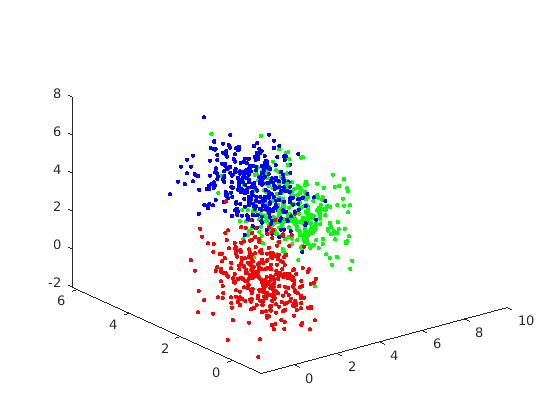

close('all');
clear;

m=[1 1 1; 5 3 2; 3 3 4]';
[l,c]=size(m);
S1=[0.8 0.2 0.1; 0.2 0.8 0.2; 0.1 0.2 0.8];
S(:,:,1)=S1;
S(:,:,2)=S1;
S(:,:,3)=S1;
P=[1/3 1/3 1/3];

% 1. Generate X1
N1=1000;
randn('seed',0)
[X1,y1]=generate_gauss_classes(m,S,P,N1);
[l,N1]=size(X1);
X1=[X1; ones(1,N1)];

% Plot X1 using different colors for points of different classes,
figure(1), plot3(X1(1,y1==1),X1(2,y1==1),X1(3,y1==1),'r.',...
    X1(1,y1==2),X1(2,y1==2),X1(3,y1==2),'g.',...
    X1(1,y1==3),X1(2,y1==3),X1(3,y1==3),'b.')


% Next, we define matrix z1, each column of which
% corresponds to a training point.
z1=zeros(c,N1);
for i=1:N1
    z1(y1(i),i)=1;
end

% Generate X2
N2=10000;
randn('seed',100)
[X2,y2]=generate_gauss_classes(m,S,P,N2);
[l,N2]=size(X2);
X2=[X2; ones(1,N2)];

% Define matrix z2
z2=zeros(c,N2);
for i=1:N2
    z2(y2(i),i)=1;
end

% Estimate the parameter vectors of the three discriminant functions
w_all=[];
for i=1:c
    w=SSErr(X1,z1(i,:),0);
    w_all=[w_all w]
end

w_all =    -0.1360
   -0.0627
   -0.1179
    1.1592


w_all =    -0.1360    0.2102
   -0.0627    0.0193
   -0.1179   -0.1214
    1.1592   -0.0652


w_all =    -0.1360    0.2102   -0.0742
   -0.0627    0.0193    0.0434
   -0.1179   -0.1214    0.2392
    1.1592   -0.0652   -0.0940


% Note: in w_all, the i-th column corresponds to the parameter vector of the i-th discriminant function.

% Compute the classification error using the set X2
[vali,class_est]=max(w_all'*X2);
err=sum(class_est~=y2)/N2

err = 0.0511

% 2. Compute the estimates of the a-posteriori probabilities, as they result in the framework
% of the LS classifier
aposte_est=w_all'*X2;

% Compute the true a posteriori probabilities
aposte=[];
for i=1:N2
    t=zeros(c,1);
    for j=1:c
        t(j)=comp_gauss_dens_val(m(:,j),S(:,:,j),X2(1:l,i))*P(j);
    end
    tot_t=sum(t);
    aposte=[aposte t/tot_t];
end

% Compute the average square error of the estimation of the posterior probabilities
approx_err=sum(sum((aposte-aposte_est).^2))/(N2*c)

approx_err = 0.0397


% 3. Compute the optimal Bayesian classification error (the true a-posteriori 
% probabilities are known)
[vali,class]=max(aposte);
err_ba=sum(class~=y2)/N2

err_ba = 0.0482

### Άσκηση 1

- Στο προηγούμενο παράδειγμα, αλλάξτε τις μέσες τιμές των τριών κλάσεων ώστε να γίνουν $m_1=[0,0,0]^T,m_2=[1,2,2]^T,m_3=[3,3,4]^T$ αντιστοίχως. Εφαρμόστε την συνάρτηση *SSErr* στο σύνολο δεδομένων $X_1$ για να εκτιμήσετε τα διανύσματα παραμέτρων $w_1, w_2, w_3$ των τριών γραμμικών συναρτήσεων διάκρισης, στον επαυξημένο $4-$διάστατο χώρο. Χρησιμοποιήστε το σύνολο $X_2$ για να υπολογίσετε την πιθανότητα λάθους.

- Υπολογίστε το λάθος ταξινόμησης του (βέλτιστου) Bayesian ταξινομητή με βάση το $X_2$ και συγκρίνετε το με αυτό που προκύπτει από τον LS ταξινομητή του βήματος 1.